# LAB 5: Specific Excess Performance of an Airbus A340-300

Authors: Niklas Gierse (nikgi434), Leonhard Mühlstrasser (leomu719)

## Lab Results

This livescript provides a SEP analysis of an Airbus A340-400.

For aircraft data such as speeds, static thrust, CL, and wing area, the provided dataset from Lab 2 was used.

For drag calculations, the script written in Lab 3 was used.

Atmospheric conditions are obtained using the ISAfunction from Lab 1.

At first, the SEP values are calculated for every height between 0 km and 15 km. To do that, the thrust and atmospheric properties are adapted to each height so that the SEP formula can be evaluated. Afterwards, some limitations are set to get rid of data outside the flight envelope. These include a maximum dynamic pressure as well as the never exceed Mach number, a maximum standard airspace speed limitation of 250 kn from ground level to 3000 m of altitude, a service ceiling for the climb rate and lastly a limitation for the lift coefficient C_l for takeoff, landing and cruise. The remaining SEP values are plotted against the altitude.

Afterwards, the time-optimal climb path is plotted by selecting the maximum SEP for every height which is still underneath the climb rate limit.

Finally the total time to to reach the service ceilings of 500 ft/min in Task 5 and 100 ft/min in Task 6 respectively is calculated by dividing the size of the altitude step by the optimal SEP value for each altitude.

### Task 2 & 3: SEP Calculation

%%%% Data Setup
clear livescript

% acdata = load('data/actable.mat')
mtow = 271000; % [kg]
staticthrust = 151000 * 4; % [N], from acdata, 4 engines
g = 9.80665; % [m/s^2]
rho0 = 1.225; % [kg/m^3]
Sref = 363.1; % [m^2]
weight = 0.8*mtow*g;

% Boundaries
vne = 365*1.852/3.6; % [m/s], indicated!
mne = 0.93;
clmax = 2.89; % TODO

altstepsize = 100;
alts = 0:altstepsize:15000;
speeds = 0:0.025:1;

servicelimit_sep = 500*(0.3048/60);


% Calculate SEP values
for iAlts=1:numel(alts)
    for iSpeeds=1:numel(speeds)
        % Calculate SEP value
        thr = calculateThrust(staticthrust, alts(iAlts), speeds(iSpeeds));

        [ignore1, ignore2, rho, a] = ISAfunction(alts(iAlts));

        vel = speeds(iSpeeds) * a;

        [pDrag, iDrag] = dragFunction(alts(iAlts), vel);

        drag = pDrag + iDrag;

        sep(iAlts,iSpeeds) = (vel/weight) * (thr - drag);

        % Remove it if outside boundaries

        % Mne
        if speeds(iSpeeds) > mne
            sep(iAlts,iSpeeds) = nan;
        end

        vne_true = vne * sqrt(rho0/rho);
        qmax = 0.5*rho*vne_true*vne_true;
        % Max dynamic pressure
        if 0.5*rho*vel*vel > qmax
            sep(iAlts,iSpeeds) = nan;
        end
        
        % Airspace speed limitation
        if alts(iAlts) <= 3000 && vel > (250*1.852/3.6)
            sep(iAlts,iSpeeds) = nan;
        end

        % CLmax
        clNeeded = weight / (Sref*0.5*rho*vel*vel);
        if clNeeded > clmax
            sep(iAlts,iSpeeds) = nan;
        end
    end
end

clear livescript

% Plot
hold off
hold on

% SEP
% contour(speeds, alts, sep);
[C,h] = contour(speeds, alts, sep, [0:5:30, 500*(0.3048/60)], 'b');
clabel(C,h);
xlabel('Mach [-]')
ylabel('Altitude [m]')
title('Flight Envelope: A340-300')
% legend('SEP [m/s]', 'Location','northwest')
xlim([0 1])

%%%% Envelope Boundaries
% clmax
altsample = 0:100:15000;
[ignore1, ignore2, rho_sample, a_sample] = ISAfunction(altsample);
spds_clmax = sqrt(weight ./ (Sref * clmax * 0.5*rho_sample)) ./ a_sample;
plot(spds_clmax, altsample, 'k', 'LineWidth',1);

% qmax
altsample = 3000:100:15000;
[ignore1, ignore2, rho_sample, a_sample] = ISAfunction(altsample);
vne_true = vne .* sqrt(rho0./rho_sample);
qmax = 0.5.*rho_sample.*vne_true.*vne_true;
spds_qmax = sqrt(2.*qmax ./ rho_sample) ./ a_sample;
plot(spds_qmax, altsample, 'k', 'LineWidth',1);

% Mne
mv_alt = 0;
plot([mne, mne], [0, 15000], 'k', 'LineWidth',1)

% airspace speed limit
% 250kts
altsample = 0:100:3000;
[ignore1, ignore2, rho_sample, a_sample] = ISAfunction(altsample);
vmax = 250*1.852/3.6;
plot(vmax./a_sample, altsample, 'k', 'LineWidth',1)
% 3000m
qmax = 0.5*rho_sample(numel(rho_sample))*vne*vne*(rho0/rho);
plot([vmax/a_sample(numel(a_sample)), sqrt(2*qmax/rho_sample(numel(rho_sample))) / a_sample(numel(a_sample))], [3000, 3000], 'k', 'LineWidth',1)

### Task 4: Time-optimal climb path

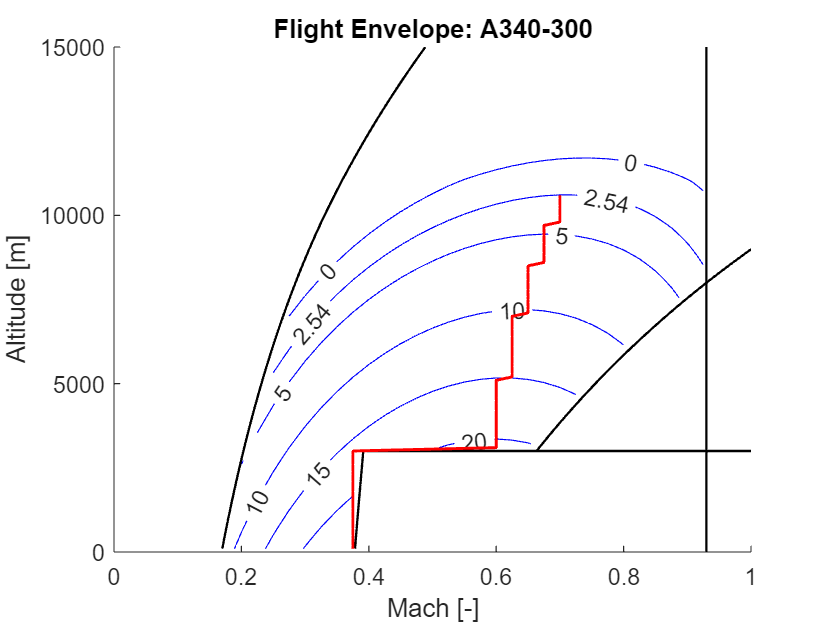

for i=1:numel(alts)
    bestSEP = max(sep(i,:));
    if bestSEP < servicelimit_sep || isnan(bestSEP)
        bestSpd(i) = nan;
    else
        bestSpd(i) = speeds(find(sep(i,:) == bestSEP));
    end
end

plot(bestSpd, alts, 'r', 'LineWidth',1.25);

### Task 5: Total time to Service Ceiling (500ft/min)

servicelimit_sep = 500*(0.3048/60);

time = 0;

% Add up time taken for each step with optimum SEP
for i=1:numel(alts)
    opt_sep = max(sep(i,:));
    if opt_sep >= servicelimit_sep
        time = time + (altstepsize/opt_sep);
    end
end

% Time to service ceiling
minutes_500fpm = time/60

minutes_500fpm = 18.0809

### Task 6: Service Ceiling 100ft/min

servicelimit_sep = 100*(0.3048/60);

time = 0;

% Add up time taken for each step with optimum SEP
for i=1:numel(alts)
    opt_sep = max(sep(i,:));
    if opt_sep >= servicelimit_sep
        time = time + (altstepsize/opt_sep);
    end
end

% Time to service ceiling
minutes_100fpm = time/60

minutes_100fpm = 27.7722

The time to climb to a ceiling of 100ft/min is significantly higher than to 500ft/min, despite the small difference in SEP. This is because the SEP at this altitude is significantly lower and consequently the vertical velocity is too. With this lower vertical velocity, it takes significantly longer to climb to higher altitudes.

## Authenticity and Plagiarism

By submitting this report, the author(s) listed above declare that this document is exclusively product of their own genuine work, and that they have not plagiarized or taken advantage from any other student’s work. If any irregularity is detected, the case will be forwarded to the University Disciplinary Board.